# 3.4. Электрический и магнитный диполи

#### Электрический дипольный момент зарядов +Q и -Q на расстоянии d

#### друг от друга

clear
syms rot(x) grad(x) div(x) sprod(x,y) vprod(x,y)
syms p Q d
p==Q*d

$$ans = p=Q\,d$$

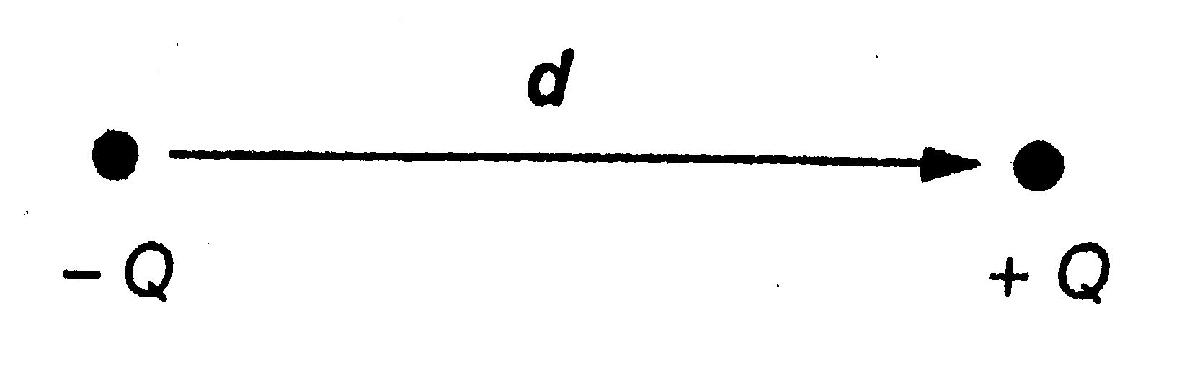

#### Магнитный дипольный момент элементарного тока

syms m I A u_N
m==I*A*u_N

$$ans = m=A\,\text{I}\,u_{N}$$

% u_N = единичный вектор

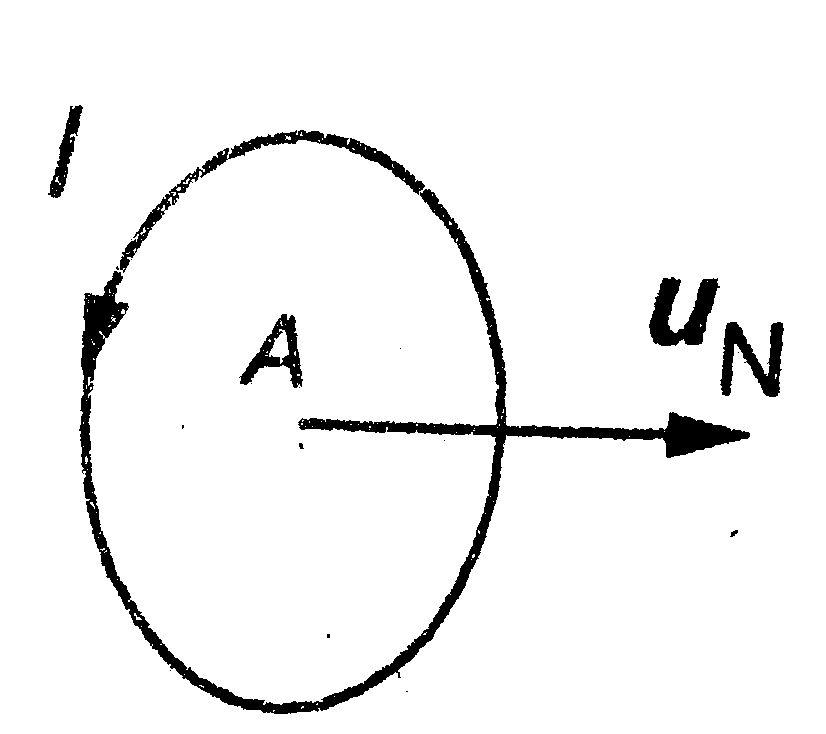

#### Потенциал вдали от электрического диполя


$$V=\frac{1}{4\pi \;\varepsilon_0 }\frac{p\;\mathrm{cos}\left(\theta \right)}{r^2 }$$


syms V epsilon0 p theta r
V==1/(4*pi*epsilon0)*p*cos(theta)/r^2

$$ans = V=\frac{p\,\cos\left(\theta \right)}{4\,\epsilon_{0}\,r^{2}\,\pi }$$

syms p r
V==1/(4*pi*epsilon0)*sprod(p,r)/r^3

$$ans = V=\frac{\mathrm{sprod}\left(p,r\right)}{4\,\epsilon_{0}\,r^{3}\,\pi }$$

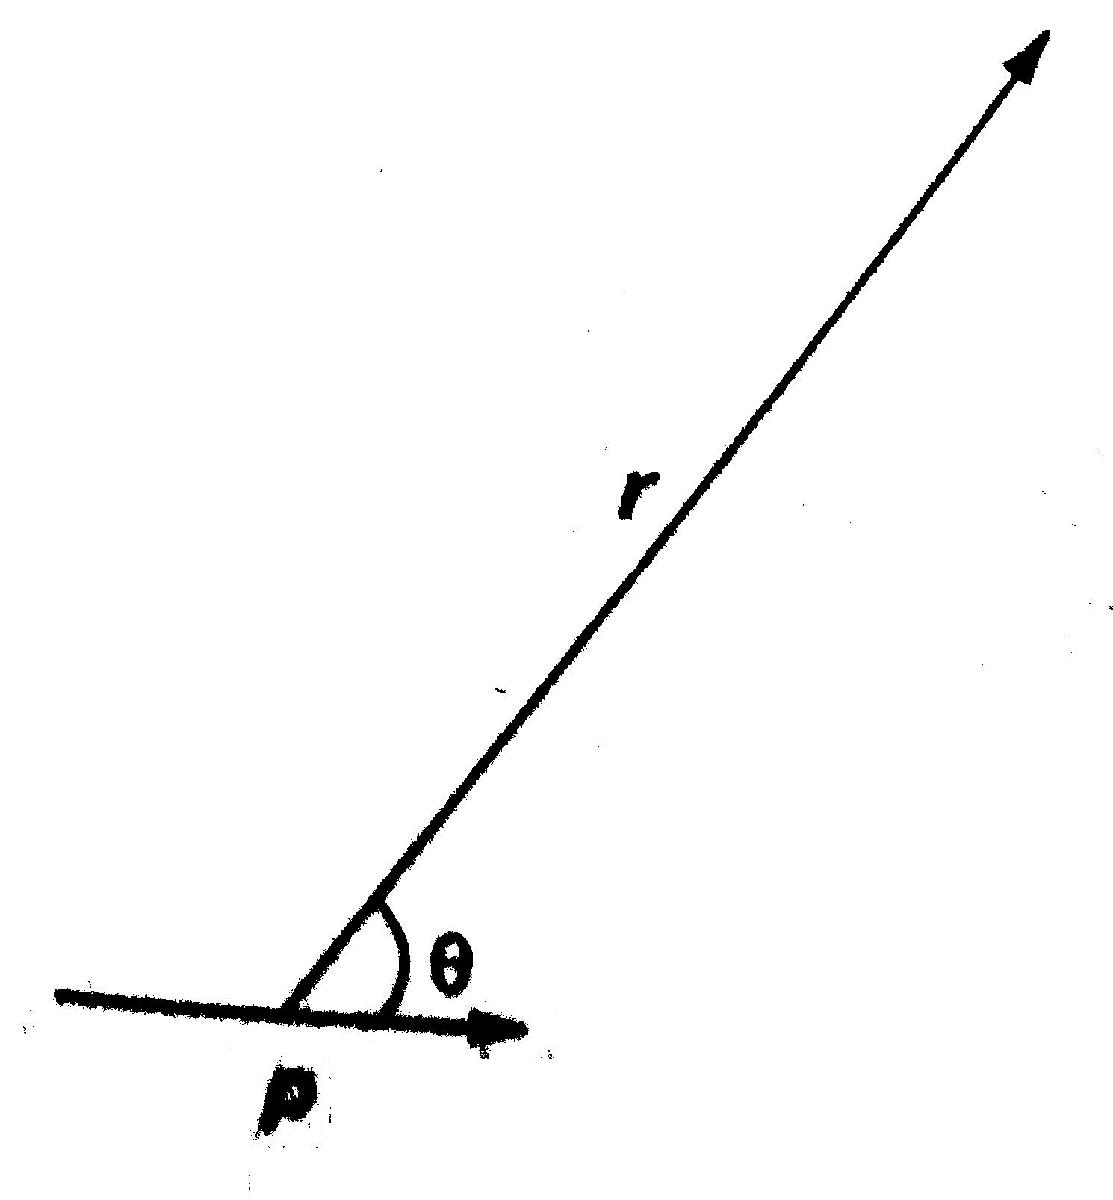

#### Электрическое поле 

syms E V
E==-grad(V)

$$ans = \text{E}=-\mathrm{grad}\left(V\right)$$

В частности, в сферических полярных координатах

syms E_r V(r) E_theta r
E_r==-diff(V)

$$ans(r) = E_{r}=-\frac{\partial }{\partial r}V\left(r\right)$$

syms V(theta)
E_theta=-1/r*diff(V)

$$E\_theta(theta) = -\frac{\frac{\partial }{\partial \theta }V\left(\theta \right)}{r}$$

#### Поле вдали от магнитного диполя

syms B_r B_theta mu0 m theta r
B_r==mu0/(4*pi)*2*m*cos(theta)/r^3

$$ans = B_{r}=\frac{m\,\mu_{0}\,\cos\left(\theta \right)}{2\,r^{3}\,\pi }$$

B_theta==(mu0/(4*pi))*m*sin(theta)/r^3

$$ans = B_{\theta }=\frac{m\,\mu_{0}\,\sin\left(\theta \right)}{4\,r^{3}\,\pi }$$

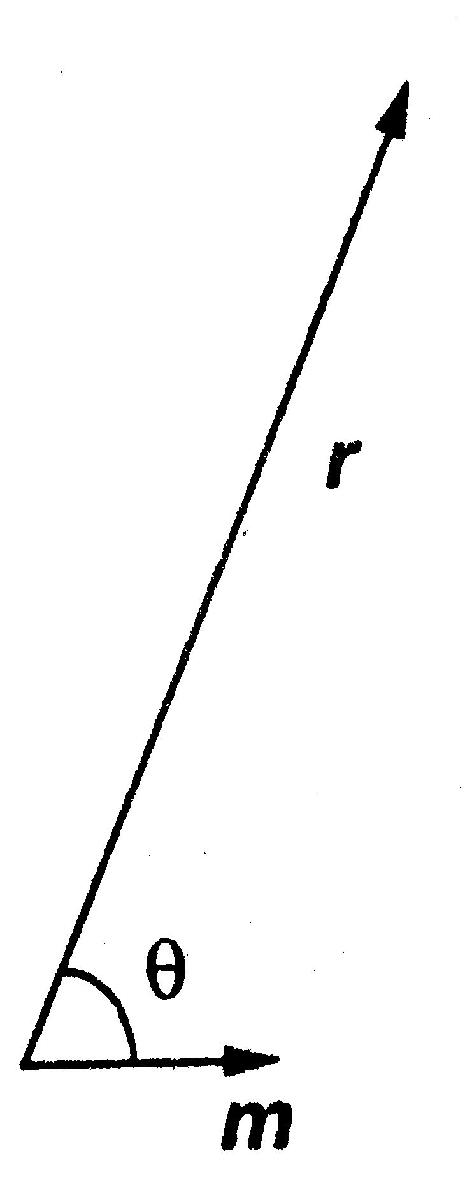

#### Векторный потенциал магнитного диполя

% A=mu0/(4*pi)*m×r/r^3
syms A m r
A==mu0/(4*pi)*vprod(m,r)/r^3

$$ans = A=\frac{\mu_{0}\,\mathrm{vprod}\left(m,r\right)}{4\,r^{3}\,\pi }$$

#### Вращающий момент диполя во внешнем поле

syms tau_e tau_m alpha B p E m B
tau_e==p*E*sin(alpha), tau_m==m*B*sin(alpha)

$$ans = \tau_{e}=\text{E}\,p\,\sin\left(\alpha \right)$$

$$ans = \tau_{m}=B\,m\,\sin\left(\alpha \right)$$

tau_e==vprod(p,E), tau_m==vprod(m,B)

$$ans = \tau_{e}=\mathrm{vprod}\left(p,\text{E}\right)$$

$$ans = \tau_{m}=\mathrm{vprod}\left(m,B\right)$$

#### Потенциальная энергия диполя во внешнем поле

syms W_e p E alpha W_m m B
W_e==-sprod(p,E)==-p*E*cos(alpha)

$$ans = \left(W_{e}=-\mathrm{sprod}\left(p,\text{E}\right)\right)=-\text{E}\,p\,\cos\left(\alpha \right)$$

W_m==-sprod(m,B)==-m*B*cos(alpha)

$$ans = \left(W_{m}=-\mathrm{sprod}\left(m,B\right)\right)=-B\,m\,\cos\left(\alpha \right)$$

#### Сила, действующая на диполь во внешнем поле

syms p nabla F E
% F=(p·nabla)E
F==(sprod(p,nabla))*E

$$ans = F=\text{E}\,\mathrm{sprod}\left(p,\mathrm{nabla}\right)$$

% F=(m·nabla)B+m*(nabla×B)
F==sprod(m,nabla)*B+m*vprod(nabla,B)

$$ans = F=B\,\mathrm{sprod}\left(m,\mathrm{nabla}\right)+m\,\mathrm{vprod}\left(\mathrm{nabla},B\right)$$

В частности, если диполь направлен вдоль x-оси и если rot(B)=0

(Сила направлена в сторону увеличения поля)

syms p_x E(x) m_x B(x)
F==p_x*diff(E), F==m_x*diff(B)

$$ans(x) = F=p_{x}\,\frac{\partial }{\partial x}\text{E}\left(x\right)$$

$$ans(x) = F=m_{x}\,\frac{\partial }{\partial x}B\left(x\right)$$

#### Электрический дипольный момент незаряженного тела

#### с распределенного заряда 

syms rho(v) r_v
p==int(r_v*rho,v)

$$ans(v) = p=\int r_{v}\,\rho \left(v\right)\mathrm{d}v$$

% v = объем тела

#### Общее определение магнитного дипольного момента

syms r j(v)
m==1/2*int(vprod(r,j),v)

$$ans = m=\frac{\int \mathrm{vprod}\left(r,j\left(v\right)\right)\mathrm{d}v}{2}$$